clc; clear all; close all; 

% Sample data
textData = fileread("sonnets.txt");
textData = replace(textData,"  ","");
textData = split(textData,[newline newline]);
textData = textData(5:2:end);
startOfTextCharacter    = compose("\x0002");
whitespaceCharacter     = compose("\x00B7");
endOfTextCharacter      = compose("\x2403");
newlineCharacter        = compose("\x00B6");
textData = startOfTextCharacter + textData;
textData = replace(textData,[" " newline],[whitespaceCharacter newlineCharacter]);
uniqueCharacters    = unique([textData{:}]);
numUniqueCharacters = numel(uniqueCharacters);
numDocuments        = numel(textData);

XTrain = cell(1,numDocuments);
YTrain = cell(1,numDocuments);
for i = 1:numel(textData)
    characters = textData{i};
    sequenceLength = numel(characters);
    
    % Get indices of characters.
    [~,idx] = ismember(characters,uniqueCharacters);
    
    % Convert characters to vectors.
    X = zeros(numUniqueCharacters,sequenceLength);
    for j = 1:sequenceLength
        X(idx(j),j) = 1;
    end
    
    % Create vector of categorical responses with end of text character.
    charactersShifted = char(append(characters(2:end),endOfTextCharacter));
    
    [~,idx] = ismember(charactersShifted,uniqueCharacters);
    
    % Convert characters to vectors.
    Y = zeros(numUniqueCharacters,sequenceLength);
    for j = 1:sequenceLength-1
        Y(idx(j),j) = 1;
    end
    
    XTrain{i} = X;
    YTrain{i} = Y;
end

maxState = 1;
for i = 1:numel(XTrain)
    [row, col] = size(XTrain{1,i});
    maxState = max(col, maxState);
end

for i = 1:numel(XTrain)
    X = [];
    X = XTrain{1,i};
    X(:, end:maxState) = 0;
    XTrain{1,i} = X;

    Y = [];
    Y = YTrain{i};
    Y(:,end:maxState) = 0;
    YTrain{i} = Y;
end


## Disadvantages

(1) it is slow (2) it requires padding if the sequences are not the same length (3) cannot take categorical variables as responses.

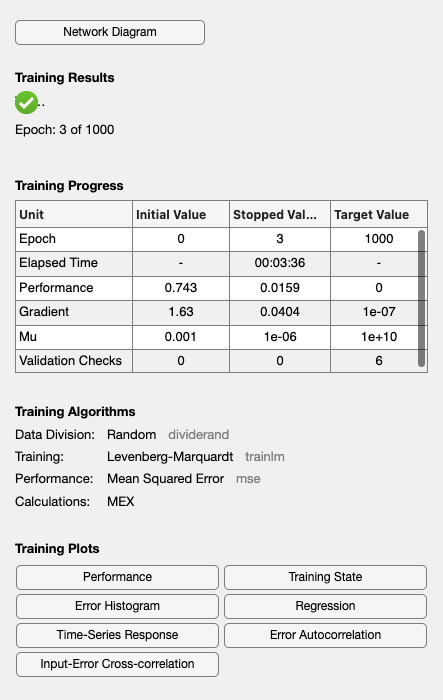


% Define the architecture of the RNN using layrecnet
numHiddenUnits = 10;
feedbackDelays = 1:5; % Specify the number of feedback delays

net = layrecnet(feedbackDelays, numHiddenUnits);

% Train the network
trainedNet = train(net, XTrain, YTrain); %, [], [], options);

## To generate text

you will have to pad yourself the text sequences generated at every step. Let's say the model was trained on 630 characters. You will start with an input vector of your first letter, and then add the model prediction as a new input. 